# Interpotation

## Lineal interpolation

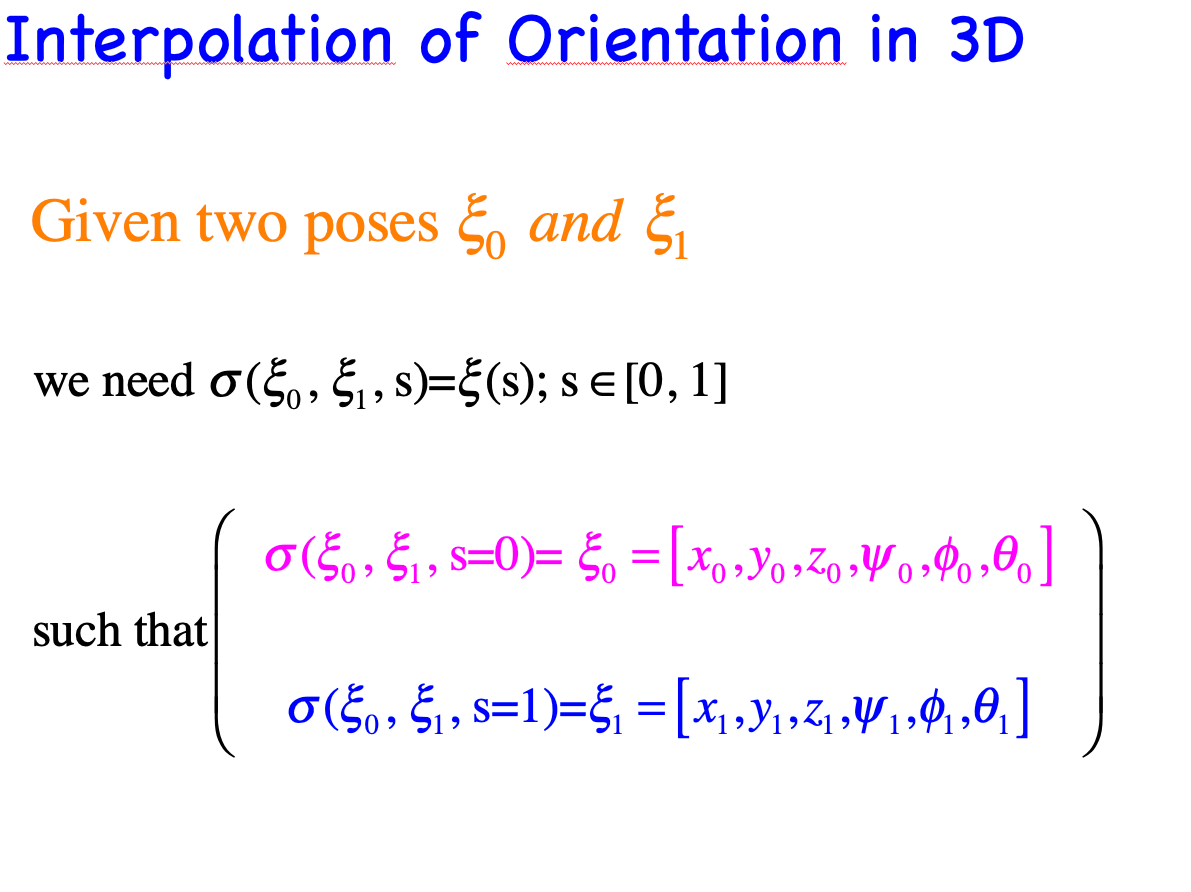

We define the initial and final poses and the transformation to be interpolated

P1=[0.1, 0.25, -0.5]

P1 =     0.1000    0.2500   -0.5000


P2=[0.7, 0.1, 0.5]

P2 =     0.7000    0.1000    0.5000


TA = transl(P1)*trotx(pi)*troty(pi);
TB = transl(P2)*trotx(pi/2)*troty(pi/2)*trotz(pi/2);
TBA = inv(TA)*TB

TBA =          0         0   -1.0000   -0.6000
         0    1.0000         0    0.1500
    1.0000         0         0    1.0000
         0         0         0    1.0000


Orientation to be interpolated

R = t2r(TBA)

R =      0     0    -1
     0     1     0
     1     0     0


### Angle-vector interpolation

[alpha vector] = tr2angvec(R);

n=200;

for i=1:n
   TRAJ1(:,:,i) = TA*transl((i-1)/n*transl(TBA))*...
       angvec2tr(alpha*(i-1)/n, vector);
end

### Visualization

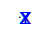

figure
view(10,30)
trplot(TA, 'color','c')
hold on 
axis([-1.5 1.5 -1.5 1.5 -1 1.5])
trplot(TB, 'color','r')
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
tranimate(TRAJ1)

### Profiles

Translation

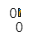

figure
P = transl(TRAJ1);
plot(P)

Orientation

figure
rpy = tr2rpy(TRAJ1)

rpy =          0         0    3.1416
         0   -0.0079    3.1416
         0   -0.0157    3.1416
         0   -0.0236    3.1416
         0   -0.0314    3.1416
         0   -0.0393    3.1416
         0   -0.0471    3.1416
         0   -0.0550    3.1416
         0   -0.0628    3.1416
         0   -0.0707    3.1416


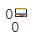

plot(rpy);

### Euler angle interpolation

angles = tr2eul(R);
n=200;
for i=1:n
   TRAJ2(:,:,i) = TA*transl((i-1)/n*transl(TBA))*...
       eul2tr(angles(1)*(i-1)/n, angles(2)*(i-1)/n, angles(3)*(i-1)/n);
end

### Visualization

figure
view(10,30)
trplot(TA, 'color','c')
hold on 
axis([-1.5 1.5 -1.5 1.5 -1 1.5])
trplot(TB, 'color','r')
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
tranimate(TRAJ2)

### Profiles

Translation

figure
P = transl(TRAJ2);
plot(P)

Orientation

figure
rpy = tr2rpy(TRAJ1)
plot(rpy);

### Cartesian interpolation

It uses quaternion and can be specify the fractional distance  along the path in the range [0 1], generated by a scalar trajectory generator such as TPOLY or LSPB (default)

S=tpoly(0,1,n)

S =          0
    0.0000
    0.0000
    0.0000
    0.0001
    0.0002
    0.0003
    0.0004
    0.0006
    0.0009


TRAJ3 = ctraj(TA, TB, 20);

### Visualization

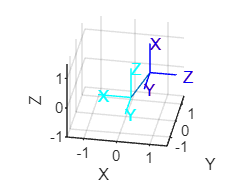

figure
view(10,30)
trplot(TA, 'color','c')
hold on 
axis([-1.5 1.5 -1.5 1.5 -1 1.5])
trplot(TB, 'color','r')
line([P1(1) P2(1)],[P1(2) P2(2)], [P1(3) P2(3)])
tranimate(TRAJ3)

### Profiles

Translation

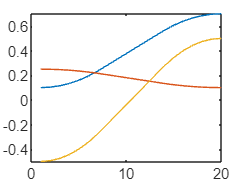

figure
P = transl(TRAJ3);
plot(P)

Orientaion

figure
rpy = tr2rpy(TRAJ3)

rpy =          0         0    3.1416
         0   -0.0098    3.1416
         0   -0.0392    3.1416
         0   -0.0881    3.1416
         0   -0.1566    3.1416
         0   -0.2448    3.1416
         0   -0.3525    3.1416
         0   -0.4754    3.1416
         0   -0.5994    3.1416
         0   -0.7234    3.1416


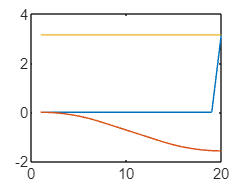

plot(rpy);

## Other interpolation commands

### Frame interpolation

clear
T0 = SE3([0.4, 0.2, 0])*SE3.rpy(0, 0, 3)

 

T0 = 
   -0.9900   -0.1411         0       0.4
    0.1411   -0.9900         0       0.2
         0         0         1         0
         0         0         0         1


T1 = SE3([-0.4, -0.2, 0.3])*SE3.rpy(-pi/4, pi/4, -pi/2)

 

T1 = 
         0    0.7071    0.7071      -0.4
   -0.7071    0.5000   -0.5000      -0.2
   -0.7071   -0.5000    0.5000       0.3
         0         0         0         1


T_i=trinterp(T0, T1, 0.5)

T_i =     0.0975   -0.7020    0.7055         0
    0.7020    0.5510    0.4512         0
   -0.7055    0.4512    0.5465    0.1500
         0         0         0    1.0000


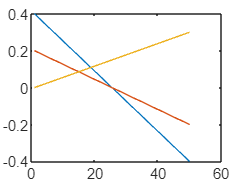

Ts = trinterp(T0, T1, 50);
P = transl(Ts);
plot(P)

rpy = tr2rpy(Ts)

rpy =          0         0    3.0000
    0.0462    0.0049    2.9312
    0.0920    0.0129    2.8627
    0.1372    0.0241    2.7947
    0.1815    0.0382    2.7272
    0.2247    0.0554    2.6603
    0.2668    0.0753    2.5941
    0.3075    0.0980    2.5288
    0.3468    0.1233    2.4642
    0.3845    0.1510    2.4005


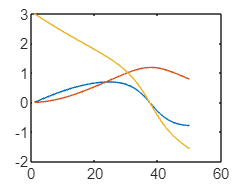

plot(rpy);

Ts = T0.interp(T1, lspb(0,1, 50) );
figure
P = Ts.transl;
about(P)

P [double] : 50x3 (1.2 kB)


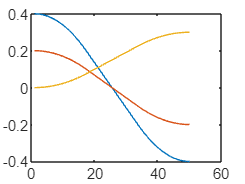

plot(P)

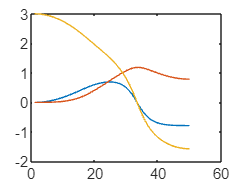

figure
rpy = Ts.torpy;
plot(rpy);

### RPY

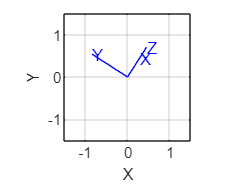

clear
R0 = SO3.Rz(-1)*SO3.Ry(-1);
R1 = SO3.Rz(1)*SO3.Ry(1);
rpy0 = R0.torpy(); rpy1 = R1.torpy();
rpy = mtraj(@tpoly, rpy0, rpy1, 50);
SO3.rpy(rpy).animate;

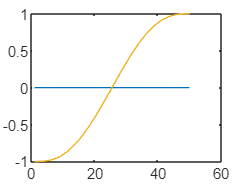

plot(rpy)

### Quaternion

q0 = R0.UnitQuaternion;
q1 = R1.UnitQuaternion;
q = interp(q0, q1, 50);
about(q)

q [UnitQuaternion] : 1x50 (1.6 kB)


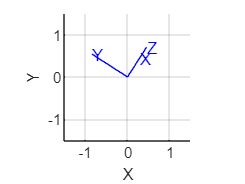

clf
q.animate()

### Direction of rotation

q0 = UnitQuaternion.Rz(-2);
q1 = UnitQuaternion.Rz(2);
q = interp(q0, q1, 50);
q.animate()

q = interp(q0, q1, 50, 'shortest');
q.animate()

## Cartesian movement

Ts = ctraj(T0,T1,50);
figure
P = Ts.transl;
about(P)

P [double] : 50x3 (1.2 kB)


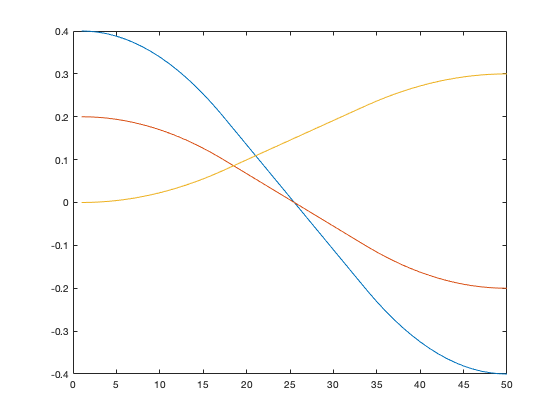


plot(P)

scatter3(P(:,1), P(:,2), P(:,3))

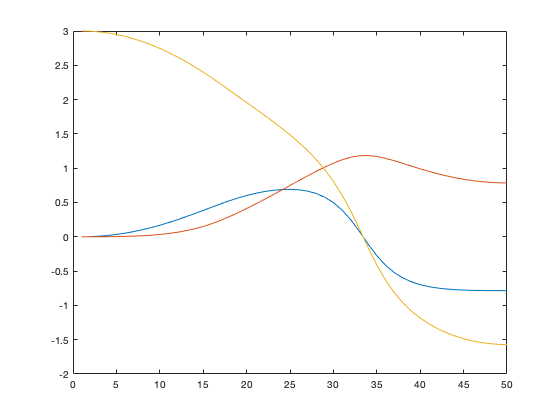

figure
rpy = Ts.torpy;
plot(rpy);